# 2025-26-ex-parcial-q1

# Problem 2

Consider the triangle mesh of Catalonia obtained loading the file `estacions.m` and which can be seen in the figure. The nodes correspond to weather stations whose longitude ($x$ variable) and latitude ($y$ variable) are recorded in the first and the second columns of the matrix named `dat`. The remaining columns correspond to the temperature (in °C) recorded at intervals of 30 min from 1 AM to 7 AM on an August night. For instance, the last column corresponds to the value of the temperature at 7 AM of the weather station of that line. The matrix named `elem` is the usual connectivity matrix.

## Part (a)

(2 points) Consider the station (node) given by the row number 54 of the `dat matrix. Assuming that we take quadratic elements on `$\Omega^{1} = [1, 2]$, $\Omega^{2} = [2, 3]$, $\Omega^{3} = [3, 4],\dots$Which is the interpolated value of the temperature (in °C) at 3h 40min?

$\bullet$ Empty answer (no penalty)

$\bullet$ 2.26556e+01

$\bullet$ 2.29889e+01

$\bullet$ 2.27667e+01 ✅

$\bullet$ 2.28778e+01

$\bullet$ 2.31000e+01

$\bullet$ 2.25444e+01

$\bullet$ 2.32111e+01

### Solution

clearvars
close all
format short e
format compact


#### Data

%-----------------------------------------------------------------------------------------------------
% Data
%-----------------------------------------------------------------------------------------------------
h = 60; %min in an hour
row = 54;
timeInterp1DHour = 3.0; %3h
timeInterp1DMin = 40.0; %40min
timeInterp1D = timeInterp1DHour * h + timeInterp1DMin; %Time to compute the average
rowToAv = 180;                                         %Row that holds the data to interpolate temperature


tempT = 24.0;                                        %Threshold temperature for part (b)

pointP = [2.5, 41.7];                                %Point to interpolate the temperature in part (c)
timeInterp2D = 1 * h;  %1 A.M.                             

timeAvSouthBCN = 5;
deg = char(176);
%----------------------------------------------------------------------------------------------------

%eval ('estacions')
%save estacions.mat dat elem
load estacions.mat -mat dat elem

[numStations,numFiles] = size(dat)

numStations =    183

numFiles =     15

numElem = size(elem,1);


#### Interpolation

%Interpolation
time= 0:30:360; time = 60 + time;
temp = dat(row,3:end);
numTimeData = size(temp,2);
elemTimeData = [1:2:numTimeData-2; 2:2:numTimeData-1; 3:2:numTimeData]';
elemTimeToInterpolate = 1 + floor( (timeInterp1D - time(1)) / h); 
nodesTimeToInterpolate = elemTimeData(elemTimeToInterpolate,:);
coefs = polyfit(time(nodesTimeToInterpolate),temp(nodesTimeToInterpolate),2);
fprintf("(a) For the row %d, interpolated value of the temperature at %dh%dmin: %.5e\n",...
    row, timeInterp1DHour, timeInterp1DMin, polyval(coefs,timeInterp1D))

(a) For the row 54, interpolated value of the temperature at 3h40min: 2.27667e+01


## Part (b)

(2 points) How many stations had a minimum temperature strictly larger than 24°C?

$\bullet$ 22

$\bullet$ Empty answer (no penalty)

$\bullet$ 24

$\bullet$ 23

$\bullet$ 26

$\bullet$ 25

$\bullet$ 20

$\bullet$ 21 ✅

### Solution

numStationsOverTempT = 0; 
for e = 1:numStations
    temp = dat(e,3:end);
    minTemp = min(temp);
    if minTemp > tempT
        numStationsOverTempT = numStationsOverTempT + 1;
    end
end
fprintf("(b) Number of stations with temperature larger than %.1f%cC: %d\n", tempT, deg, numStationsOverTempT)

(b) Number of stations with temperature larger than 24.0°C: 21


## Part (c)

(3 points) Which is the interpolated temperature at 1h AM at the point with coordinates $(2.5,41.7)$?

$\bullet$ 2.33010e+01

$\bullet$ 2.40396e+01

$\bullet$ 3.43680e+01

$\bullet$ 3.42122e+01

$\bullet$ 2.40489e+01 ✅

$\bullet$ 2.14762e+01

$\bullet$ Empty answer (no penalty)

$\bullet$ 3.03443e+01

### Solution

nodTemp = 3 + floor((timeInterp2D- time(1)) / h);
for e = 1:numElem
    nodes = elem(e,:);
    vertices = dat(nodes,1:2);
    [alphas, isInside]=baryCoord(vertices, pointP);
    if isInside > 0
        temp = dat(nodes,nodTemp);
        intepolatedTemp = alphas * temp;
        break
    end
end
fprintf("(c) Interpolated temperature at point (%.1f, %.1f): %.5e%cC\n", pointP', intepolatedTemp, deg)

(c) Interpolated temperature at point (2.5, 41.7): 2.40489e+01°C


## Part (d)

(3 points) Consider the stations at the Meditarranean coast below Barcelona, which lie at the boundary between Station 69 in the Southwest and station 167 in the Northeast, both included (see Figure). Which is the average (mean) temperature at 5 h AM?

![Temperatures Catalonia](cattemp.png)

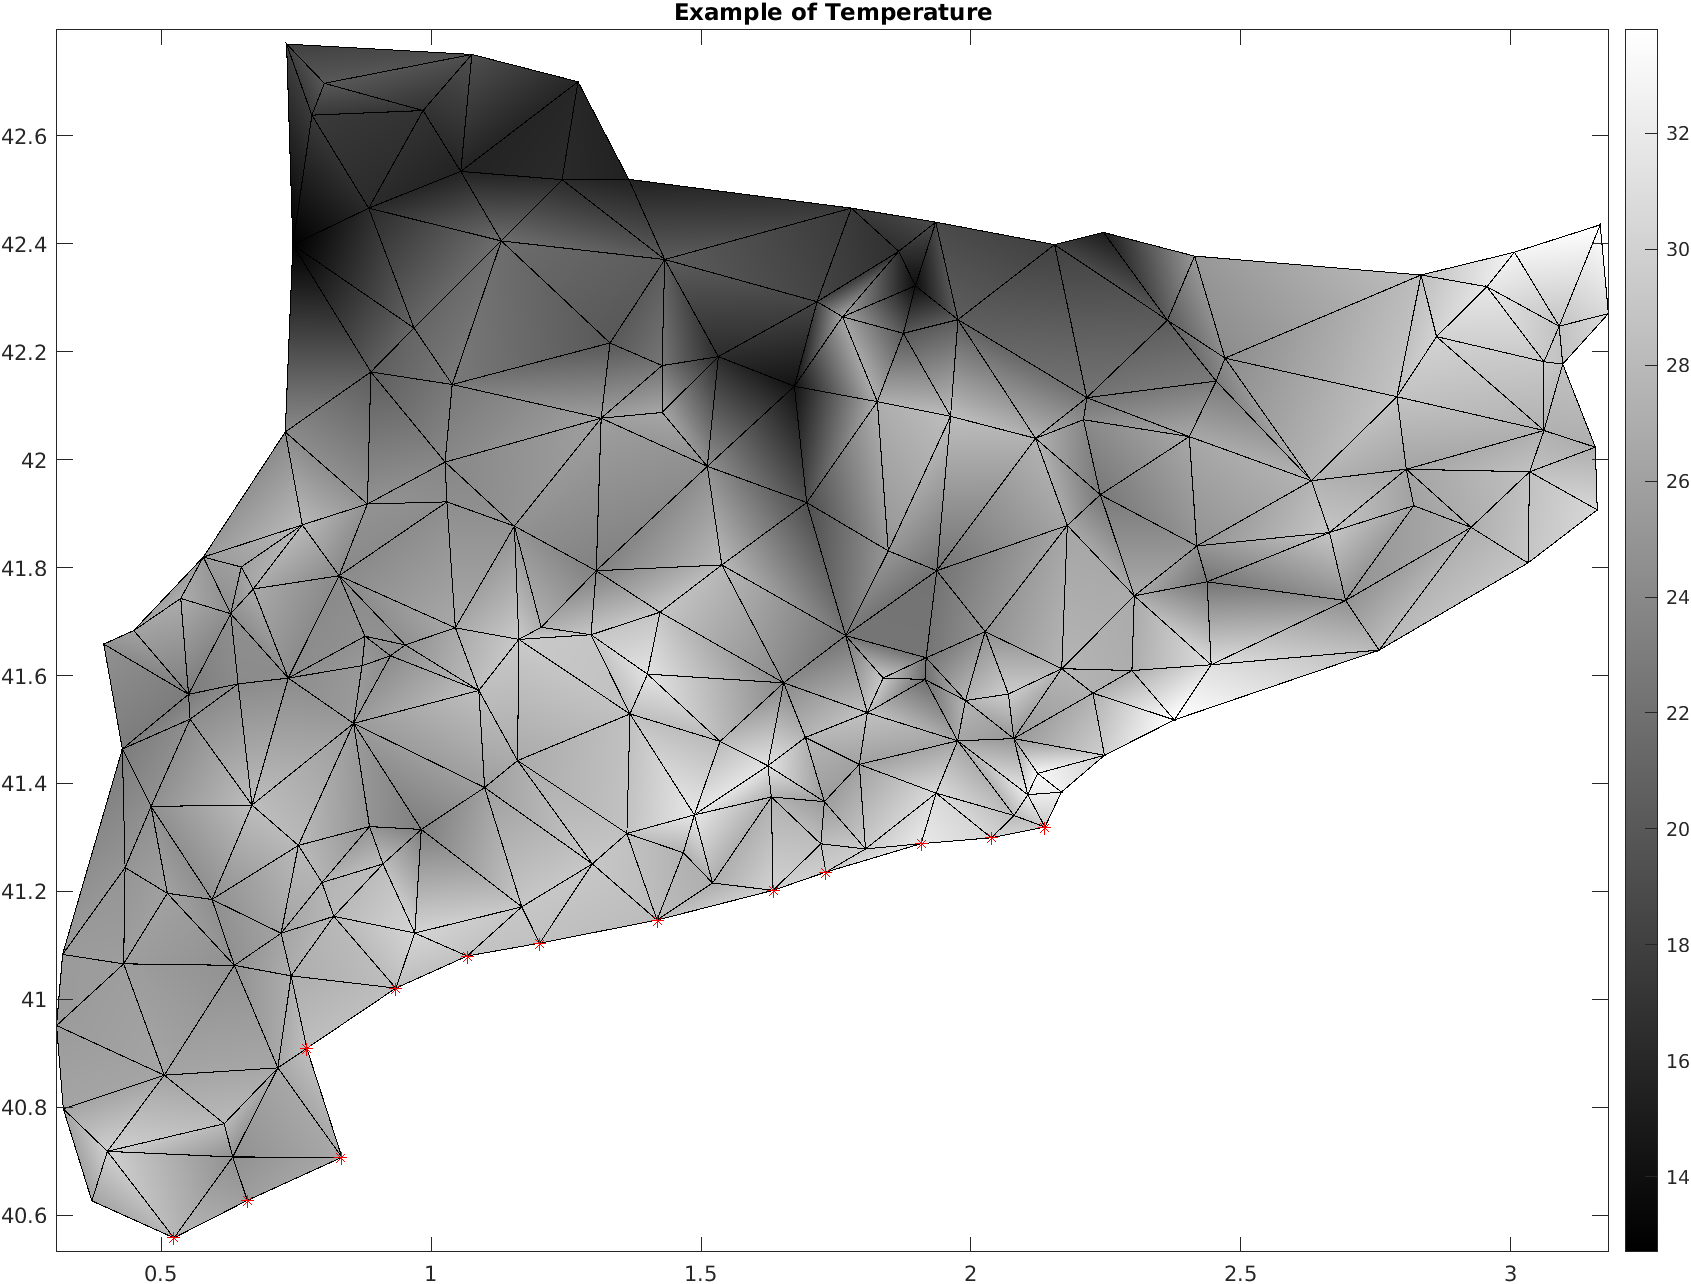

$\bullet$ 1.97777e+01

$\bullet$ 3.06482e+01

$\bullet$ 2.31178e+01

$\bullet$ Empty answer (no penalty)

$\bullet$ 1.82818e+01

$\bullet$ 3.17282e+01

$\bullet$ 2.35385e+01 ✅

$\bullet$ 3.28733e+01

### Solution

#### Nodes on the boundary

indNodesBd = boundaryNodes(dat(:,1:2), elem);

#### Box coordinates

x1 = dat(69,1);
x2 = dat(167,1);
y1 = dat(69,2);
y2 = dat(167,2);

nodTemp = 3 + 2 * (timeAvSouthBCN - 1);

#### Nodes in the box that lie on the coast

%indexos = find(dat(indNodesBd,1) >= x1 & dat(indNodesBd,1) <= x2 & ...
%   dat(indNodesBd,2) >= y1 & dat(indNodesBd,2) <= y2)
indexos = dat(indNodesBd,1) >= x1 & dat(indNodesBd,1) <= x2 & ...
    dat(indNodesBd,2) >= y1 & dat(indNodesBd,2) <= y2;
nodesSouthBCN = indNodesBd(indexos);
plotElements(dat(:,1:2), elem, 0);

#### Plot of the mesh. The nodes on the coast between the specified coordinates bolted in red

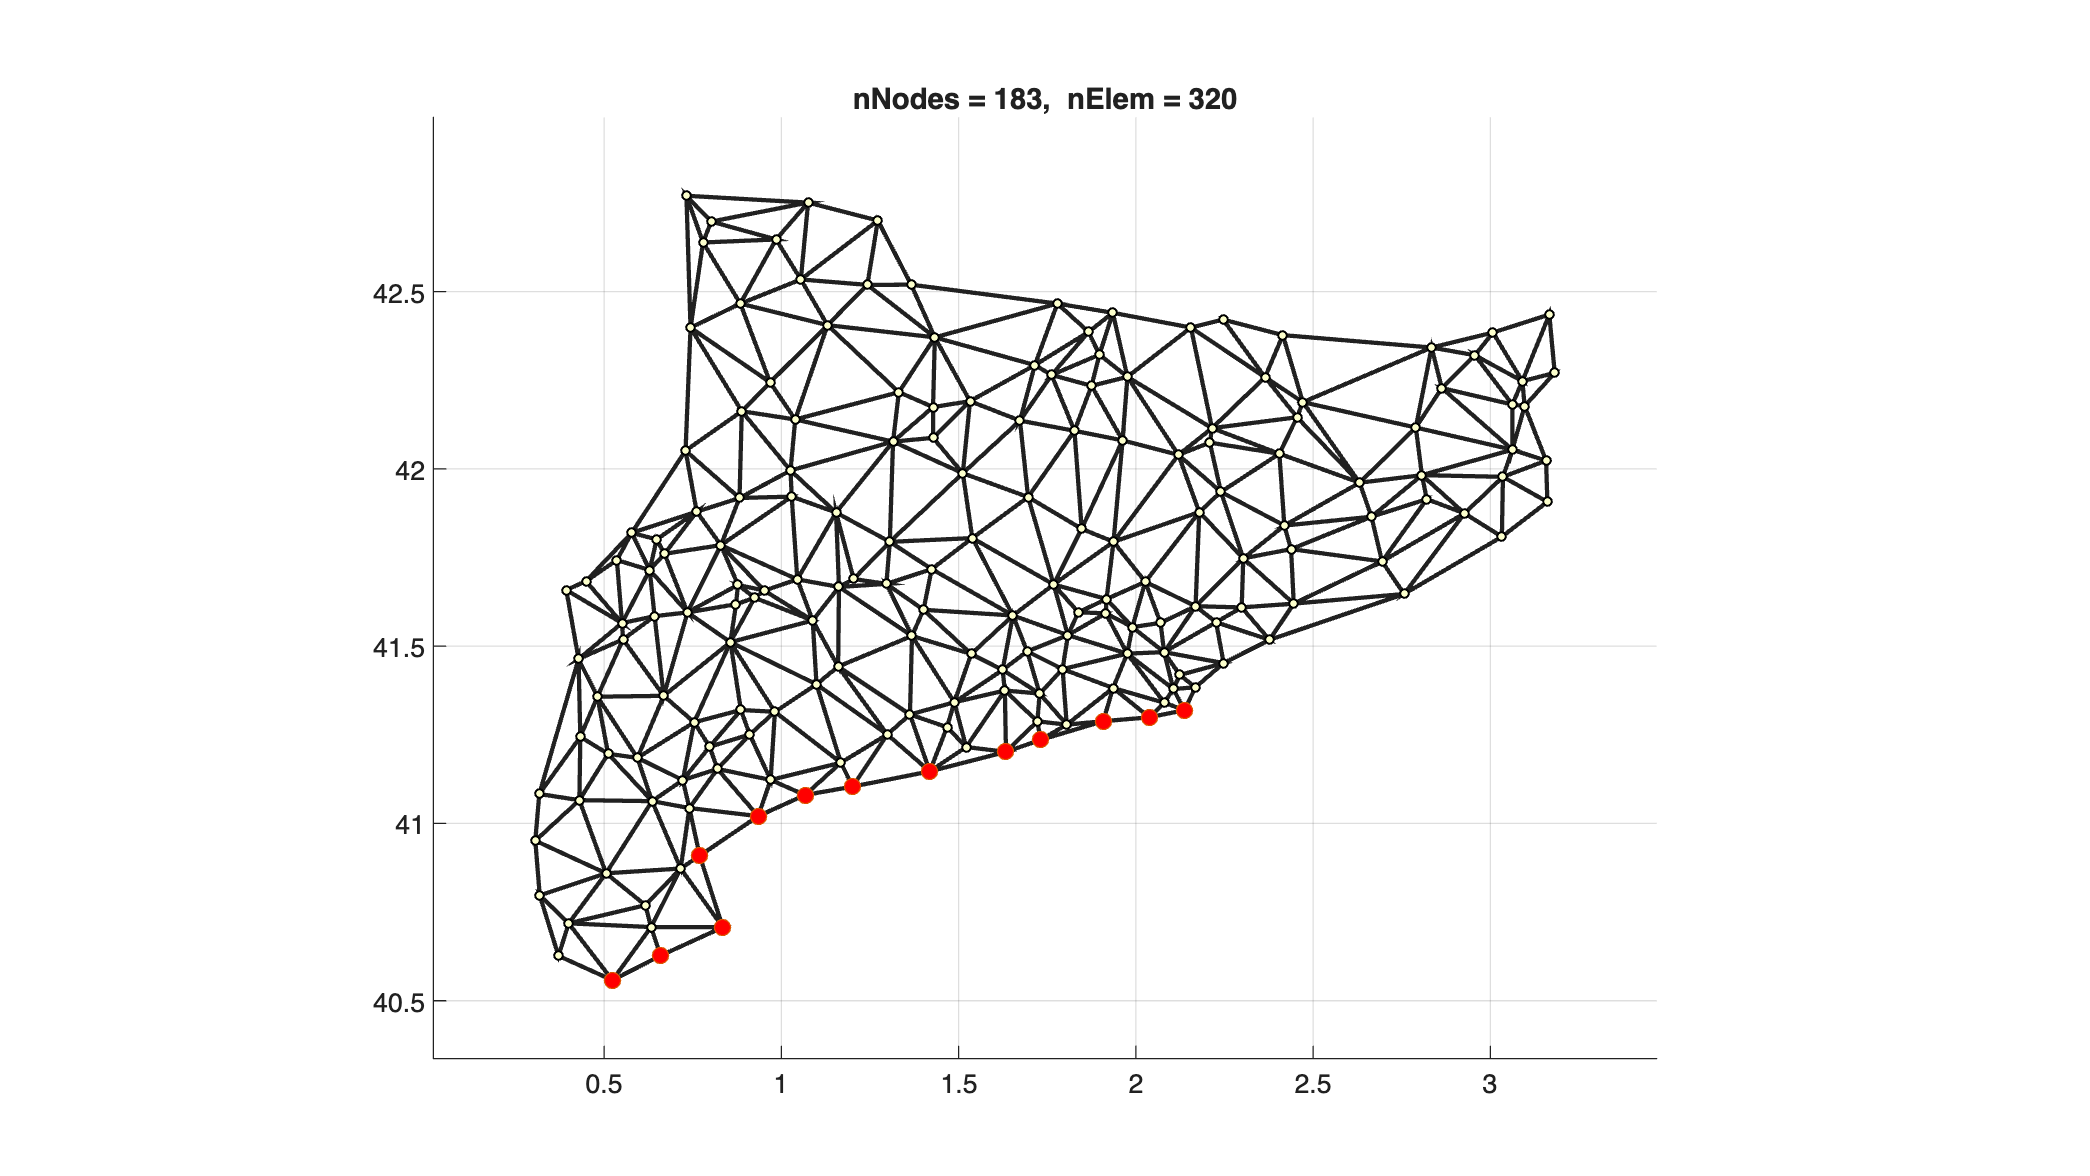

hold on
plot(dat(nodesSouthBCN,1), dat(nodesSouthBCN,2),'o',MarkerFaceColor='red')

#### Catalan coast's average temperature's computation form the selected nodes

tempSouthBCN=dat(nodesSouthBCN,nodTemp);
size(tempSouthBCN,1);
avTemp = sum(tempSouthBCN) / size(tempSouthBCN,1);
fprintf("(d) Averaged (mean) temperature at %.2fh AM: %.5e%cC\n", timeAvSouthBCN, avTemp, deg)

(d) Averaged (mean) temperature at 5.00h AM: 2.35385e+01°C


Print all the soluitons at once:

fprintf(['Solutions:\n' ...
    '(a) For the row %d, interpolated value of the temperature at %dh%dmin: %.5e\n',...
    '(b) Number of stations with temperature larger than %.1f: %d\n',...
    '(c) Interpolated temperature at point (%.1f, %.1f): %.5e\n',...
    '(d) Averaged (mean) temperature at %.2fh AM: %.5e\n'],...
    row, timeInterp1DHour, timeInterp1DMin, polyval(coefs,timeInterp1D),...
    tempT, numStationsOverTempT,...
    pointP', intepolatedTemp,...
    timeAvSouthBCN, avTemp)

Solutions:
(a) For the row 54, interpolated value of the temperature at 3h40min: 2.27667e+01
(b) Number of stations with temperature larger than 24.0: 21
(c) Interpolated temperature at point (2.5, 41.7): 2.40489e+01
(d) Averaged (mean) temperature at 5.00h AM: 2.35385e+01
